## Load Data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Groundwater'
cd ThermalEfficiency\data\input\
load('Bflat30min.mat')
% This code is to identify seaonal changes in temp scaling factor and to id scaling factor relationship to depth. This is the preferred code for determining the seasonal thermal efficiency. 
% Input data has been cropped to select periods with little/no rain,
% averaged to weekly values, and water level and soil temperature have been
% moderately smoothed. Data is analyzed on month to month basis, because of
% few number points linear fit is inappropriate so the median weekly gradient is
% used. Final scaling factor is filtered for data fit and qualitatively
% asessed (period with only thermal effects on level should have
% flat/little change in water level.  

%A trend with decreasing themral efficiency with increasing water depth was
%identified in BLM37, which have some of the longest data periods
%and are most isolated from outside water sources. BLM93 showed an inverse
%relationship. Further work/data needed, for now using a constant number
%seems the best (range of +/- 0.6 for both for thermal scaling


#### This code inputs trimmed datasets and analyzes the change using monthly averages over the whole dataset

### BLM 64 (insufficent data)

### BLM 63 (moderate uncertainty)

cd cropped\
load('BLM63clipped.mat')
well_ThermEff = ThermEff(BLM63, 63);
BLM63_ThermEff = namebars(well_ThermEff)

BLM63_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare      rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    ________    ______    ______________    ______    _________________

         9.5909            1.424       5.5075     0.052762    2.3213       0.93468          63              1        
         1.8694           1.4306       5.7302      0.14197    1.1378       0.91888          63              2        


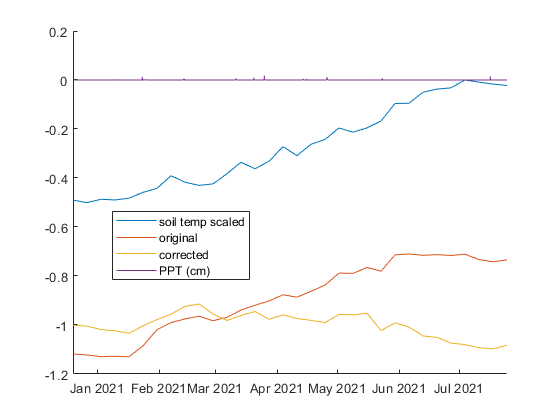

cd ..\
load('BLM63_AirPresCor.mat')
BLM63 = retime(BLM63, "weekly",'mean');
BLM63_ThermEffValue = mean(BLM63_ThermEff.MedianRatio);
BLM63 =  BaroCorrection(BLM63, mean(BLM63_ThermEff.MedianRatio), Bflat30min);

### BLM 12 (high uncertainty)

cd cropped\
load('BLM12clipped.mat')
% BLM12 = retime(BLM12, "weekly","mean");

well_ThermEff = ThermEff(BLM12, 50.2);
BLM12_ThermEff = namebars(well_ThermEff)

BLM12_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

         1.7582           1.8166       1.7874     0.74441    2.8953        0.6301         50.2             1        
         2.4125           2.1884       2.0854      0.5328    2.4479       0.64929         50.2             2        


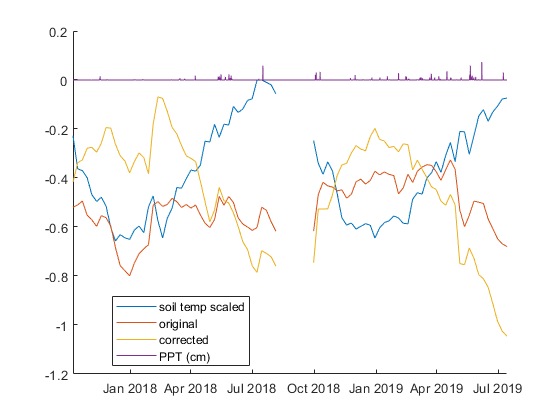

cd ..\
load('BLM12_AirPresCor.mat')
BLM12 = retime(BLM12, "weekly",'mean');
BLM12_ThermEffValue = mean(BLM12_ThermEff.MedianRatio);
BLM12 =  BaroCorrection(BLM12, mean(BLM12_ThermEff.MedianRatio), Bflat30min);

### BLM 53B (BLM 53 is the same but shorter time period)

cd cropped\
load('BLM53Bclipped.mat')
BLM53B = retime(BLM53B, "weekly","mean");

well_ThermEff = ThermEff(BLM53B, 50.2);
BLM53B_ThermEff = namebars(well_ThermEff)

BLM53B_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse      MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    _______    ______________    ______    _________________

         4.3878           1.6296       3.0087     0.29588     1.7987       0.58404         50.2             1        
         3.9675           2.0467       4.1777     0.52404    0.86384       0.59175         50.2             2        


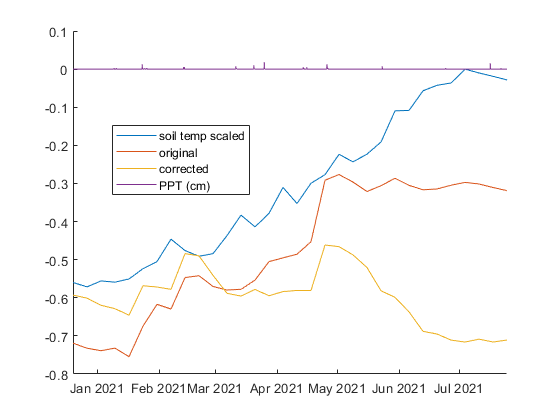

cd ..\
load('BLM53B_AirPresCor.mat')
BLM53B = retime(BLM53B, "weekly",'mean');
BLM53B_ThermEffValue = mean(BLM53B_ThermEff.MedianRatio(1));
BLM53B =  BaroCorrection(BLM53B, BLM53B_ThermEff.MedianRatio(1), Bflat30min);

### BLM 50B

cd cropped\
load('BLM50Bclipped.mat')
BLM50B = retime(BLM50B, "weekly","mean");

well_ThermEff = ThermEff(BLM50B, 50.2);
BLM50B_ThermEff = namebars(well_ThermEff)

BLM50B_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

            NaN           3.5726         NaN          NaN       NaN       0.075357        50.2             1        
         1.4392           1.8269         NaN      0.81547    2.0887        0.11796        50.2             2        


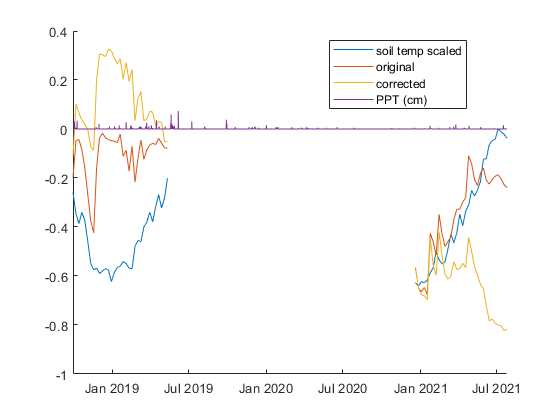

cd ..\
load('BLM50B_AirPresCor.mat')
BLM50B = retime(BLM50B, "weekly",'mean');
BLM50B_ThermEffValue = BLM50B_ThermEff.MedianRatio(2);
BLM50B =  BaroCorrection(BLM50B, BLM50B_ThermEff.MedianRatio(2), Bflat30min);

### BLM 45

cd cropped\
load('BLM45clipped.mat')
BLM45 = retime(BLM45, "weekly","mean");

well_ThermEff = ThermEff(BLM45, 45);
BLM45_ThermEff = namebars(well_ThermEff)

BLM45_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average     rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    ________    _______    ______    ______________    ______    _________________

        -0.81777          1.7603        0.47125     0.9991    0.4015       0.18332          45              1        
         0.49339            1.35       -0.16219    0.64593    1.4936       0.23323          45              2        


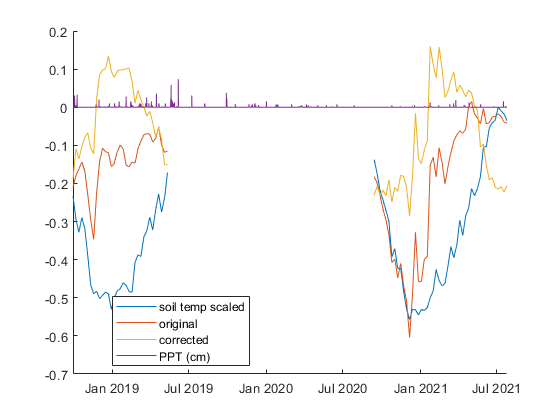

cd ..\
load('BLM45_AirPresCor.mat')
BLM45 = retime(BLM45, "weekly",'mean');
BLM45_ThermEffValue = mean(BLM45_ThermEff.MedianRatio);
BLM45 =  BaroCorrection(BLM45, mean(BLM45_ThermEff.MedianRatio), Bflat30min);

### BLM 43A (Moderate uncertainty here)

cd cropped\
load('BLM43Aclipped.mat')
well_ThermEff = ThermEff(BLM43A, 43.1);
BLM43A_ThermEff = namebars(well_ThermEff)

BLM43A_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

         5.0229           5.4884       5.2556           1       NaN           NaN         43.1             1        
         1.8085           2.1196       3.4157     0.32034    2.6252       0.37206         43.1             2        


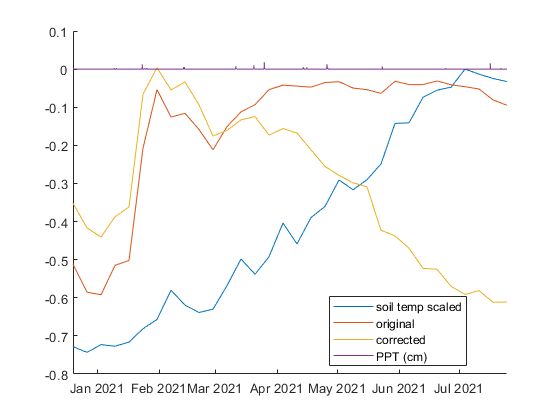

cd ..\
load('BLM43A_AirPresCor.mat')
BLM43A = retime(BLM43A, "weekly",'mean');
BLM43A_ThermEffValue = BLM43A_ThermEff.MedianRatio(2);
BLM43A =  BaroCorrection(BLM43A,  BLM43A_ThermEff.MedianRatio(2), Bflat30min);

### BLM 37

cd cropped\
load('BLM37clipped.mat')
% BLM37 = retime(BLM37, "weekly","mean");
well_ThermEff = ThermEff(BLM37, 37);
BLM37_ThermEff = namebars(well_ThermEff)

BLM37_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse      MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    _______    ______________    ______    _________________

         0.41127          0.84299      0.62713    0.97044    0.74921        0.1892          37              1        
        0.097031          0.86847      0.25415    0.50939    0.70518       0.19174          37              2        


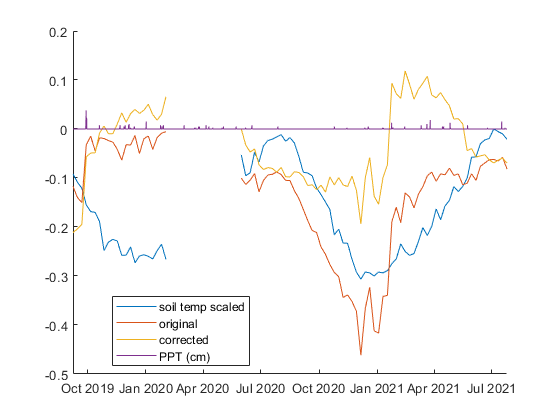

cd ..\
load('BLM37_AirPresCor.mat')
BLM37 = retime(BLM37, "weekly",'mean');
BLM37_ThermEffValue = mean(BLM37_ThermEff.MedianRatio);
BLM37 =  BaroCorrection(BLM37, mean(BLM37_ThermEff.MedianRatio), Bflat30min);

### BLM 41

cd cropped\
load('BLM41clipped.mat')
well_ThermEff = ThermEff(BLM41, 41);
BLM41_ThermEff = namebars(well_ThermEff)

BLM41_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

         8.4307           1.9683       5.1995     0.98169    2.8709       0.76677          41              1        
         2.1089           2.4519       5.2698     0.41348    4.0356           NaN          41              2        


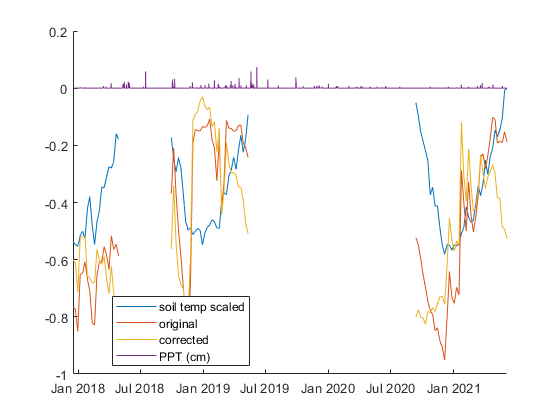

cd ..\
load('BLM41_AirPresCor.mat')
BLM41 = retime(BLM41, "weekly",'mean');
BLM41_ThermEffValue = BLM41_ThermEff.MedianRatio(1);
BLM41 =  BaroCorrection(BLM41, BLM41_ThermEff.MedianRatio(1), Bflat30min);

### BLM 34 (not fully satisfactory)

cd cropped\
load('BLM34clipped.mat')
well_ThermEff = ThermEff(BLM34, 34);
BLM34_ThermEff = namebars(well_ThermEff)

BLM34_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

        -44.342           -1.8821      -23.112          1       NaN       0.26684          34              1        
          2.753             2.958      -20.795    0.77555    2.0705       0.30149          34              2        


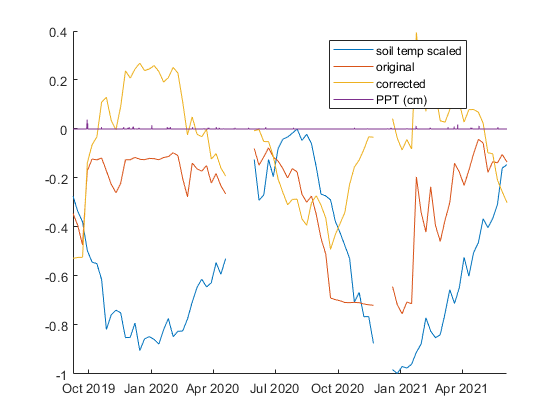

cd ..\
load('BLM34_AirPresCor.mat')
BLM34 = retime(BLM34, "weekly",'mean');
BLM34_ThermEffValue = BLM34_ThermEff.MedianRatio(2);
BLM34_ThermEffValue = 2.2;
BLM34 =  BaroCorrection(BLM34, BLM34_ThermEff.MedianRatio(2), Bflat30min);

### BLM 31

cd cropped\
load('BLM31clipped.mat')
well_ThermEff = ThermEff(BLM31, 31);
BLM31_ThermEff = namebars(well_ThermEff)

BLM31_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    ______    ______________    ______    _________________

        -604.21           1.5154       -301.35          1       NaN       0.91611          31              1        
         1.1209            1.369       -301.54    0.46574    2.6466       0.83956          31              2        


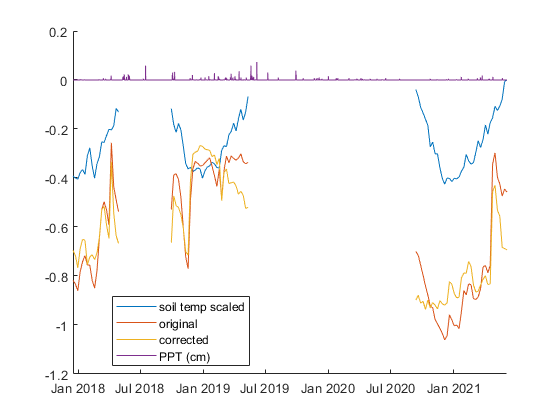

cd ..\
load('BLM31_AirPresCor.mat')
BLM31 = retime(BLM31, "weekly",'mean');
BLM31_ThermEffValue = mean(BLM31_ThermEff.MedianRatio);
BLM31 =  BaroCorrection(BLM31, mean(BLM31_ThermEff.MedianRatio), Bflat30min);

### BLM 16A (Needs more data)

% cd ..\
load('BLM16A_AirPresCor.mat')
BLM16A  = retime(BLM16A, 'weekly', 'mean');
well = BLM16A;
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well_ThermEff = ThermEff(well, 16.1);

BLM16A_ThermEff = namebars(well_ThermEff)

BLM16A_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse      MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    _______    ______________    ______    _________________

         2.2297           0.46536      1.3475         NaN        NaN       0.063028        16.1             1        
        0.55697           0.57841      1.3933     0.80644    0.36669       0.063028        16.1             2        


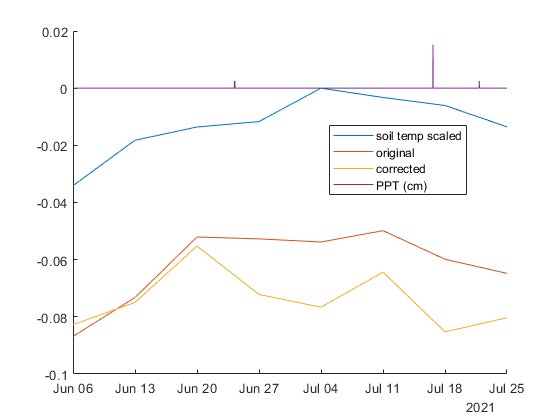

BLM16A_ThermEffValue = mean(BLM16A_ThermEff.MedianRatio);
BLM16A =  BaroCorrection(BLM16A, mean(BLM16A_ThermEff.MedianRatio), Bflat30min);

### BLM 16

load('BLM16_AirPresCor.mat')
BLM16 = BLM16(BLM16.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor > 0.02 , :); %screen out periods when water level near/above surface
BLM16  = retime(BLM16, 'weekly', 'mean');

well = BLM16;
well.SoilTemp_C = smoothdata(well.SoilTemp_C,'movmedian','SmoothingFactor',0.05,...
    'SamplePoints',well.Date_Time_MDT);
well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor = ...
    smoothdata(well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor,...
    'movmedian','SmoothingFactor',0.05,'SamplePoints',well.Date_Time_MDT);

well_ThermEff = ThermEff(well, 16);
BLM16_ThermEff = namebars(well_ThermEff)

BLM16_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average     rsquare     rmse      MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    ________    _______    _______    ______________    ______    _________________

         -1.8376           1.076       -0.38081    0.63667     1.1084       0.10955          16              1        
       -0.031532          0.4946       -0.93459    0.43129    0.66133       0.10502          16              2        


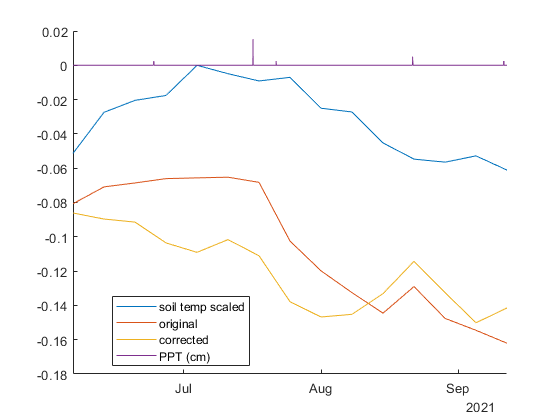

load('BLM16_AirPresCor.mat')
BLM16 = retime(BLM16, "weekly",'mean');
BLM16_ThermEffValue = mean(BLM16_ThermEff.MedianRatio);
BLM16 =  BaroCorrection(BLM16, mean(BLM16_ThermEff.MedianRatio), Bflat30min);

### BLM 93

cd cropped\
load('BLM93clipped.mat')
well_ThermEff = ThermEff(BLM93, 93.0);
BLM93_ThermEff = namebars(well_ThermEff)

BLM93_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare     rmse      MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    _______    _______    ______________    ______    _________________

        0.65508           1.0575       0.85631    0.41333     2.7448       0.22388          93              1        
        0.12583           1.0733       0.39045    0.45271    0.77395       0.19816          93              2        


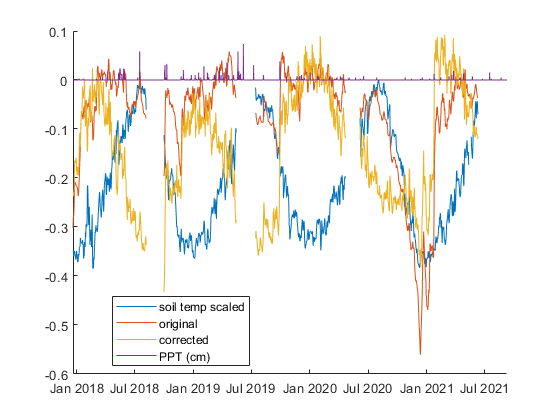

cd ..\
load('BLM93_AirPresCor.mat')
BLM93 = retime(BLM93, "daily",'mean');
BLM93_ThermEffValue = mean(BLM93_ThermEff.MedianRatio);
BLM93 =  BaroCorrection(BLM93, mean(BLM93_ThermEff.MedianRatio), Bflat30min);

### BLM 93C

cd cropped\
load('BLM93Cclipped.mat')

well_ThermEff = ThermEff(BLM93C, 93.3);
BLM93C_ThermEff = namebars(well_ThermEff)

BLM93C_ThermEff = 2×8 table
    LinearRegression    MedianRatio    Average    rsquare      rmse     MeanWaterLevel    WellID    1isMonth2isWeekly
    ________________    ___________    _______    ________    ______    ______________    ______    _________________

         2.1698           0.84115      1.5055     0.013492    9.9539       0.15088         93.3             1        
        0.47944           0.88385      1.3246      0.35356    0.9201       0.15242         93.3             2        


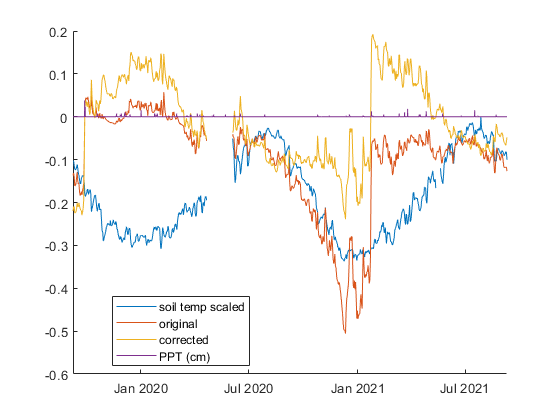

cd ..\
load('BLM93C_AirPresCor.mat')
BLM93C = retime(BLM93C, "daily",'mean');
BLM93C_ThermEffValue = mean(BLM93C_ThermEff.MedianRatio);
BLM93C =  BaroCorrection(BLM93C, mean(BLM93C_ThermEff.MedianRatio), Bflat30min);

#### Combine data

ThermEffSummary = [[BLM37_ThermEffValue, "BLM37"];
    [BLM93_ThermEffValue, "BLM93"]; 
    [BLM93C_ThermEffValue, "BLM93C"]; 
    [BLM63_ThermEffValue, "BLM63"]; 
    [BLM43A_ThermEffValue, "BLM43A"]; 
    [BLM50B_ThermEffValue, "BLM50B"]; 
    [BLM53B_ThermEffValue, "BLM53B"]; 
    [BLM45_ThermEffValue, "BLM45"]; 
    [BLM41_ThermEffValue, "BLM41"];
    [BLM31_ThermEffValue, "BLM31"];
    [BLM12_ThermEffValue, "BLM12"];
    [BLM34_ThermEffValue, "BLM34"];
 [BLM16_ThermEffValue, "BLM16"]]

ThermEffSummary = 13×2 string array
    "0.85573"    "BLM37" 
    "1.0654"     "BLM93" 
    "0.8625"     "BLM93C"
    "1.4273"     "BLM63" 
    "2.1196"     "BLM43A"
    "1.8269"     "BLM50B"
    "1.6296"     "BLM53B"
    "1.5551"     "BLM45" 
    "1.9683"     "BLM41" 
    "1.4422"     "BLM31" 
    "2.0025"     "BLM12" 
    "2.2"        "BLM34" 
    "0.78531"    "BLM16" 


ThermEffSummary = sortrows(ThermEffSummary,1);
% [BLM16A_ThermEffValue, "BLM16A"];

## Save data

cd ..\output\
save("ThermEffSummary.mat", 'ThermEffSummary')
save("BLM93C_ThermEff.mat", 'BLM93C')
save("BLM93_ThermEff.mat", 'BLM93')
save("BLM41_ThermEff.mat", 'BLM41')
save("BLM34_ThermEff.mat", 'BLM34')
save("BLM31_ThermEff.mat", 'BLM31')

function well_ThermEff = ThermEff(well, wellID)


### Monthly

wellhourly = retime(well, "monthly","mean");
wellhourly.gradient_pressure = gradient(wellhourly.SoilTemp_C); %linear fit for Thermal efficiency
wellhourly.gradient_waterlevel = -gradient(wellhourly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor);

### Linear regression determination

idxValid = ~isnan(wellhourly.gradient_pressure);
wellhourly = wellhourly(idxValid, :);
idxValid = ~isnan(wellhourly.gradient_waterlevel);

if numel(wellhourly.gradient_pressure(idxValid)) > 1
[fitting, error] = fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1');
well_ThermEff(1, 1) = fitting(1);
well_ThermEff(1, 4) = error.rsquare;
well_ThermEff(1, 5) = error.rmse;

else 
well_ThermEff(1, 1) = NaN;
well_ThermEff(1, 4) = NaN;
well_ThermEff(1, 5) = NaN;

end
% figure
% hold on
% scatter(wellhourly.gradient_pressure, wellhourly.gradient_waterlevel*100)
% plot(fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1'))
% title(uniquemonths(ii))
% xlabel('Hourly d soil temp. (^oC)')
% ylabel('d water level (cm)')

## Median ratio method

wellhourly.dwdb = ((wellhourly.gradient_waterlevel*100)./wellhourly.gradient_pressure);
well_ThermEff(1, 2) = median(wellhourly.dwdb, 'omitnan');

#### Add other values

well_ThermEff(1, 3) = mean(well_ThermEff(1:2)); 

well_ThermEff(1, 6) = mean(wellhourly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor); 
well_ThermEff(1, 7) = wellID;
well_ThermEff(1, 8) = 1;


### Weekly

wellhourly = retime(well, "weekly","mean");
wellhourly.gradient_pressure = gradient(wellhourly.SoilTemp_C); %linear fit for Thermal efficiency
wellhourly.gradient_waterlevel = -gradient(wellhourly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor);

### Linear regression determination

idxValid = ~isnan(wellhourly.gradient_pressure);
wellhourly = wellhourly(idxValid, :);
idxValid = ~isnan(wellhourly.gradient_waterlevel);

if numel(wellhourly.gradient_pressure(idxValid)) > 1
[fitting, error] = fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1');
well_ThermEff(2, 1) = fitting(1);
well_ThermEff(2, 4) = error.rsquare;
well_ThermEff(2, 5) = error.rmse;

else 
well_ThermEff(2, 1) = NaN;
well_ThermEff(2, 4) = NaN;
well_ThermEff(2, 5) = NaN;

end
% figure
% hold on
% scatter(wellhourly.gradient_pressure, wellhourly.gradient_waterlevel*100)
% plot(fit(wellhourly.gradient_pressure(idxValid), wellhourly.gradient_waterlevel(idxValid)*100, 'poly1'))
% title(uniquemonths(ii))
% xlabel('Hourly d soil temp. (^oC)')
% ylabel('d water level (cm)')

## Median ratio method

wellhourly.dwdb = ((wellhourly.gradient_waterlevel*100)./wellhourly.gradient_pressure);
well_ThermEff(2, 2) = median(wellhourly.dwdb, 'omitnan');

#### Add other values

well_ThermEff(2, 3) = mean(well_ThermEff(1:2)); 

well_ThermEff(2, 6) = mean(wellhourly.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor); 
well_ThermEff(2, 7) = wellID;
well_ThermEff(2, 8) = 2;

end

function well = BaroCorrection(well, ThermEff, Bflat30min)
ThermEff = -ThermEff;
well.gradient_soiltemp = gradient(well.SoilTemp_C)*(ThermEff); %linear fit for Thermal efficiency - see external table
well.gradient_soiltemp_cumsum = cumsum(well.gradient_soiltemp, 'omitnan');
well.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo = ((well.gradient_soiltemp_cumsum + well.EquivalentHead_HaliteSaturated_BelowSurf_m*-100) -mean(well.gradient_soiltemp_cumsum)/2)/-100;
well.soilTempScaled = -well.SoilTemp_C*(ThermEff)/100 + max(well.SoilTemp_C)*(ThermEff)/100;

figure
hold on
plot(well.Date_Time_MDT, -well.SoilTemp_C*(ThermEff)/100 + max(well.SoilTemp_C)*(ThermEff)/100, 'DisplayName','soil temp scaled') %0.05 added as a down shift
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor, 'DisplayName','original')
plot(well.Date_Time_MDT, -well.EquivalentHead_HaliteSaturated_BelowSurf_m_ThermCo, 'DisplayName','corrected')
plot(Bflat30min.Date_Time_MDT, Bflat30min.PPT_mm/100, 'DisplayName','PPT (cm)')

well = removevars(well, {'gradient_soiltemp','gradient_soiltemp_cumsum'});

xlim(well.Date_Time_MDT([1,end]))
legend('Location',"best")
end

function well_ThermEff = namebars(well_ThermEff)
well_ThermEff = array2table(well_ThermEff);
well_ThermEff.Properties.VariableNames{1} = 'LinearRegression';
well_ThermEff.Properties.VariableNames{2} = 'MedianRatio';
well_ThermEff.Properties.VariableNames{3} = 'Average';
well_ThermEff.Properties.VariableNames{4} = 'rsquare';
well_ThermEff.Properties.VariableNames{5} = 'rmse';
well_ThermEff.Properties.VariableNames{6} = 'MeanWaterLevel';
well_ThermEff.Properties.VariableNames{7} = 'WellID';
well_ThermEff.Properties.VariableNames{8} = '1isMonth2isWeekly';
end 